% Query all input devices
info = audiodevinfo;

fprintf('\n--- Available Input Devices ---\n');


--- Available Input Devices ---


if isempty(info.input)
    disp('No input devices found.');
else
    % Create a table for easy reading
    Devices = {info.input.Name}';
    IDs = [info.input.ID]';
    T = table(IDs, Devices);
    disp(T);
end

    IDs                               Devices                           
    ___    _____________________________________________________________

     0     {'Primary Sound Capture Driver (Windows DirectSound)'       }
     1     {'Microphone (USBAudio1.0):1 (Windows DirectSound)'         }
     2     {'Microphone (USBAudio1.0):2 (Windows DirectSound)'         }
     3     {'Microphone Array (Realtek(R) Audio) (Windows DirectSound)'}




% Specific check for your IDs (1 and 2)
checkIDs = [1, 2];
for id = checkIDs
    try
        devName = audiodevinfo(1, id); % 1 indicates 'input'
        fprintf('ID %d is valid: %s\n', id, devName);
    catch
        fprintf('ID %d is INVALID or not connected.\n', id);
    end
end

ID 1 is valid: Microphone (USBAudio1.0):1 (Windows DirectSound)
ID 2 is valid: Microphone (USBAudio1.0):2 (Windows DirectSound)


Fs = 48000; 
nBits = 16;
nChannels = 1;

rec1 = audiorecorder(Fs, nBits, nChannels, 2); 
rec2 = audiorecorder(Fs, nBits, nChannels, 3); 

disp("Start Recording")

Start Recording


record(rec1); 
record(rec2); 
pause(10);  
stop(rec1);
stop(rec2);
disp("End of recording.")

End of recording.



mic1 = getaudiodata(rec1);
mic2 = getaudiodata(rec2);

% data = readmatrix('mic_data_40cm.csv');
% mic1 = data(:,1);
% mic2 = data(:,2);
% Fs = 40000; %Humans can hear up to about 20,000 Hz.
% nBits = 16;

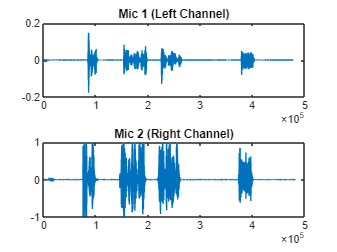

figure;
subplot(2,1,1); plot(mic1); title('Mic 1 (Left Channel)');
subplot(2,1,2); plot(mic2); title('Mic 2 (Right Channel)');

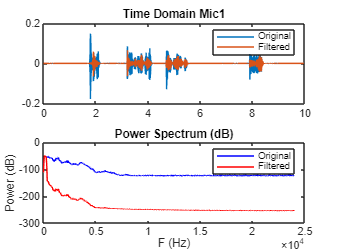

minLength = min(length(mic1), length(mic2));
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);
t = (0:minLength-1) * (1/Fs);



% Lowpass
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);


% Mic 1
figure; subplot(2,1,1);
plot(t, mic1); hold on; plot(t, mic1_f);
title('Time Domain Mic1'); legend('Original','Filtered');

subplot(2,1,2);
[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on; plot(ff1, 10*log10(pf1), 'r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');

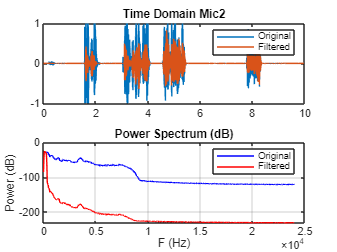


% Mic 2
figure; subplot(2,1,1);
plot(t, mic2); hold on; plot(t, mic2_f);
title('Time Domain Mic2'); legend('Original','Filtered');

subplot(2,1,2);
[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), '-b'); hold on; plot(ff2, 10*log10(pf2), '-r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
grid on;

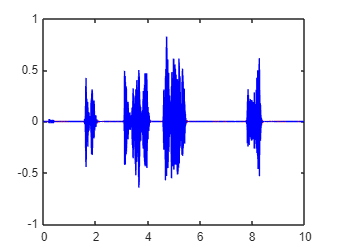


figure;
plot(t,mic1_f,"r")
hold on
plot(t,mic2_f,"b")
hold off

% TDOA
mic_spacing_m = 1; % Set your actual mic spacing in meters
v_sound = 343;     % m/s
max_delay_s = mic_spacing_m / v_sound;   % e.g. ~0.003 s
max_lag_samples = round(max_delay_s * Fs) ;  
% Normalized cross-correlation (GCC-style, time domain)
[xc12, lags12] = xcorr(mic1_f, mic2_f, max_lag_samples, 'normalized');
[~, idx12] = max(abs(xc12));
lag12       = lags12(idx12);
delay12     = lag12 / Fs;

fprintf('Lag:   %d samples\n', lag12);

Lag:   95 samples


fprintf('Delay: %.6f s  (%.4f ms)\n', delay12, delay12*1000);

Delay: 0.001979 s  (1.9792 ms)



v = 343; 
disp("dist of mic")

dist of mic


distance_mic = delay12 * v

distance_mic = 0.6789

fprintf('Distance: %.3f\n',distance_mic);

Distance: 0.679


L = 0.5;
% angle12 = rad2deg(acos(distance_diff/0.5))
